clc; clear all; close all;

## Tutorial 6.1

Se creó la función **Iint.m**

## Tutorial 6.2

Se creó la función** cmpc.m**

## Ejemplo 6.3

% testcmpc.m
Am=[-1 0 0;0 -3 0;3 3 -5];
Bm=[1 0;0 1; 1 1];
Cm=[1 0 0;0 1 0];
[m1,n1]=size(Cm);
[n1,n_in]=size(Bm);
A=zeros(n1+m1,n1+m1);
A(1:n1,1:n1)=Am;
A(n1+1:n1+m1,1:n1)=Cm;
B=zeros(n1+m1,n_in);
B(1:n1,:)=Bm;
C=zeros(m1,n1+m1);
C(:,n1+1:n1+m1)=eye(m1,m1);
Q=C'*C;
R=0.2*eye(2,2);
p1=1.5;
p2=2;
N1=4;
N2=4;
p=[p1 p2];
N=[N1 N2];
Tp=10;

[Omega,Psi]=cmpc(A,B,p,N,Tp,Q,R);

[Ap1,L1]=lagc(p1,N1)

Ap1 =    -1.5000         0         0         0
   -3.0000   -1.5000         0         0
   -3.0000   -3.0000   -1.5000         0
   -3.0000   -3.0000   -3.0000   -1.5000


L1 =     1.7321
    1.7321
    1.7321
    1.7321


[Ap2,L2]=lagc(p2,N2)

Ap2 =     -2     0     0     0
    -4    -2     0     0
    -4    -4    -2     0
    -4    -4    -4    -2


L2 =      2
     2
     2
     2



Lzerot=zeros(2,N1+N2)

Lzerot =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


Lzerot(1,1:N1)=L1'

Lzerot =     1.7321    1.7321    1.7321    1.7321         0         0         0         0
         0         0         0         0         0         0         0         0


Lzerot(2,N1+1:N1+N2)=L2'

Lzerot =     1.7321    1.7321    1.7321    1.7321         0         0         0         0
         0         0         0         0    2.0000    2.0000    2.0000    2.0000



K_mpc=Lzerot*(Omega\Psi);
Acl=A-B*K_mpc;
eig(Acl)

ans =   -5.0000 + 0.0000i
  -2.8993 + 0.0000i
  -0.7233 + 0.0000i
  -1.1508 + 0.9270i
  -1.1508 - 0.9270i



[K,S,E]=lqr(A,B,Q,R);

## Tutorial 6.3

Se creó la función **cssimuob.m**

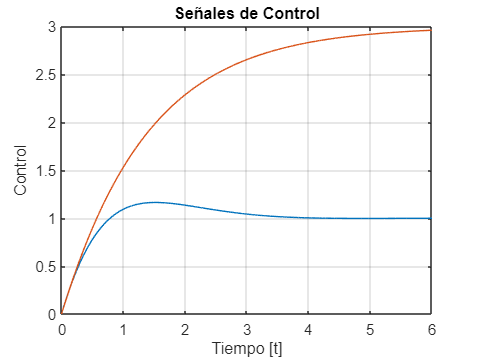

Q1=eye(n1+m1,n1+m1);
R1=0.0001*eye(m1,m1);
K_ob=lqr(A',C',Q1,R1)';

xm=zeros(n1,1);
u0=zeros(n_in,1);
y0=zeros(m1,1);
N_sim=60000;

h=0.0001;
r1=ones(1,N_sim+200);
r2=zeros(1,N_sim+200);
sp=[r1;r2];

[u,y,udot,t]=cssimuob(xm,u0,y0,sp,Am,Bm,Cm,A,B,C,N_sim,Omega,Psi,K_ob,Lzerot,h);

figure(1)
plot(t,u)
grid on
xlabel('Tiempo [t]')
ylabel('Control')
title('Señales de Control')

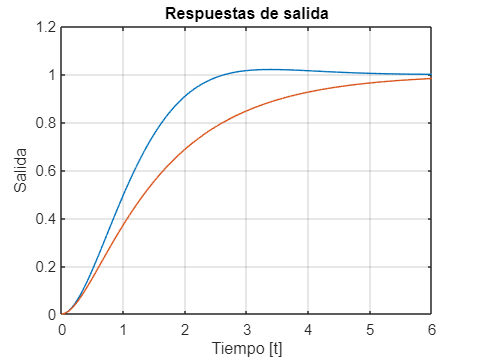


figure(2)
plot(t,y)
grid on
xlabel('Tiempo [t]')
ylabel('Salida')
title('Respuestas de salida')

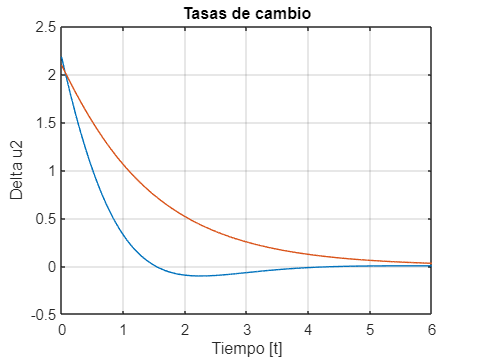


figure(3)
plot(t,udot)
grid on
xlabel('Tiempo [t]')
ylabel('Delta u2')
title('Tasas de cambio')